In the name of allah

# Linear Control Systems

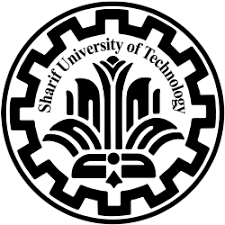

Hw 03

ali sadeghian 400101464

Fall 1402

# Theory Assignments

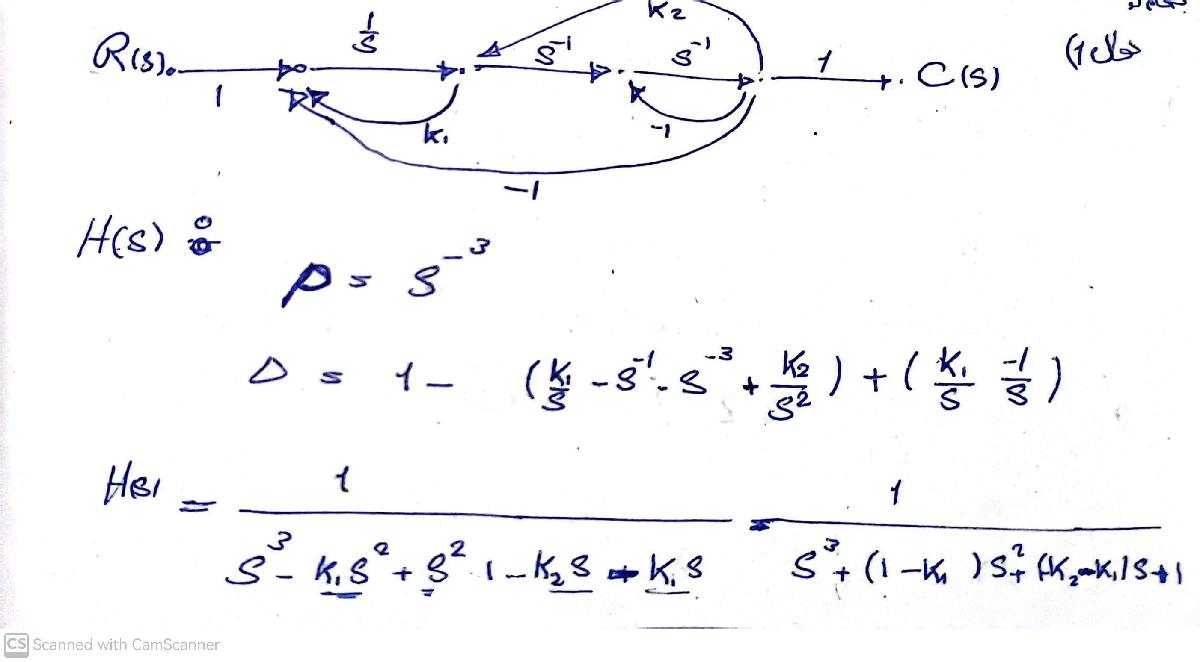

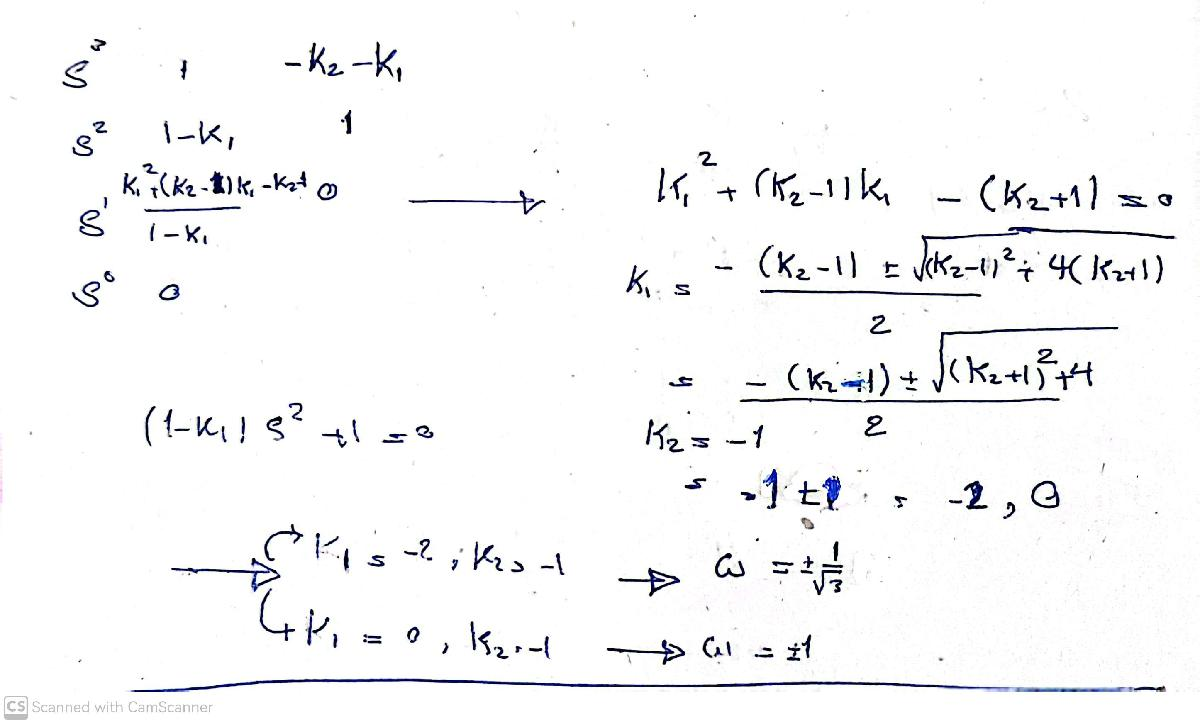

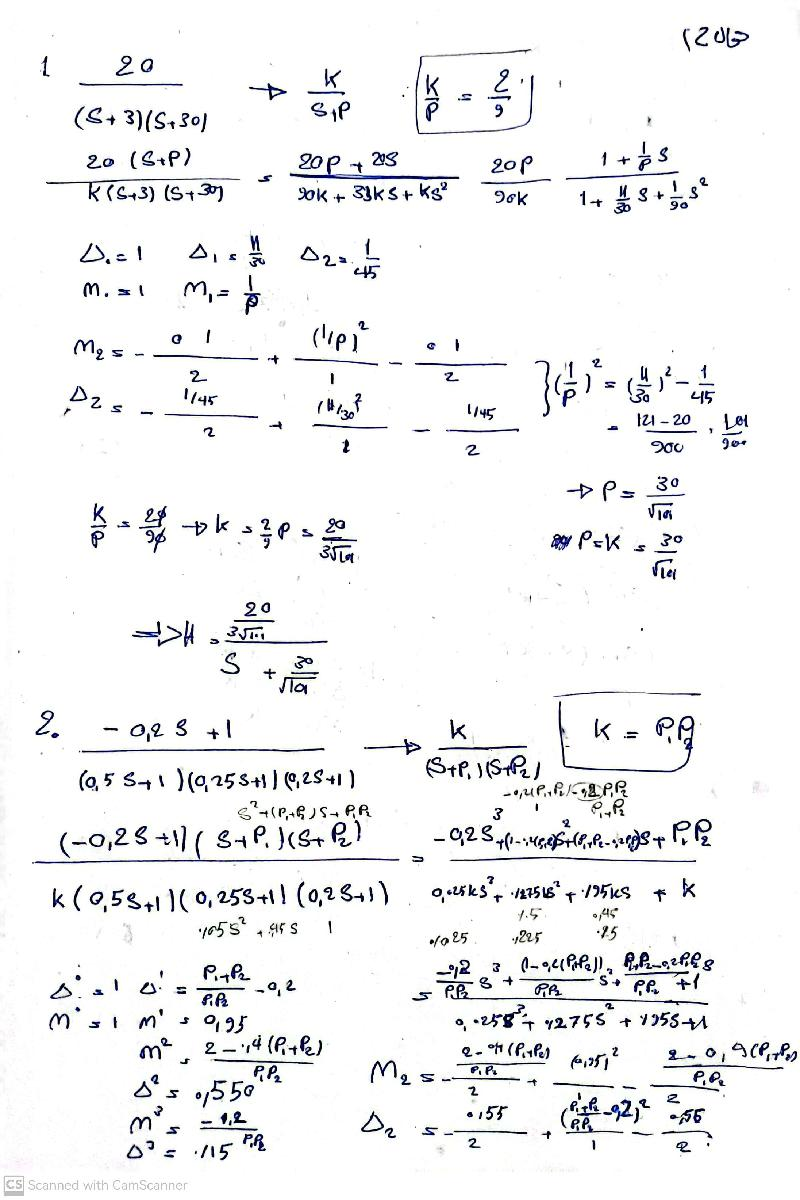

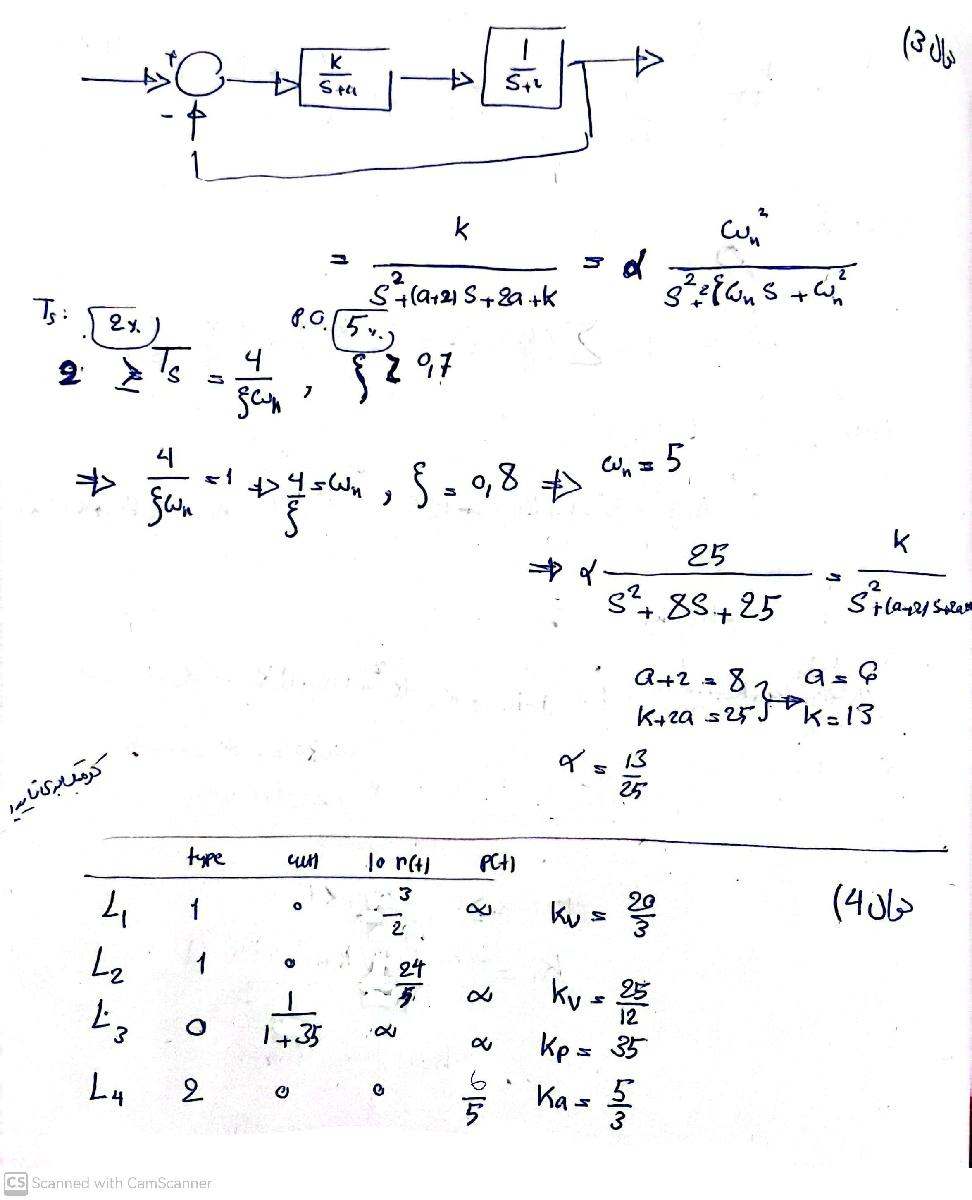

num = [13];
den = [1 8 25];
sys = tf(num, den)

sys =
 
        13
  --------------
  s^2 + 8 s + 25
 
Continuous-time transfer function.




t = 0:0.01:10;
u =  Step01(t);
y = lsim(sys, u, t);
Max = max(y);
PO = ((Max-13/25)/(13/25)) *100 % P.O.

PO = 1.5163

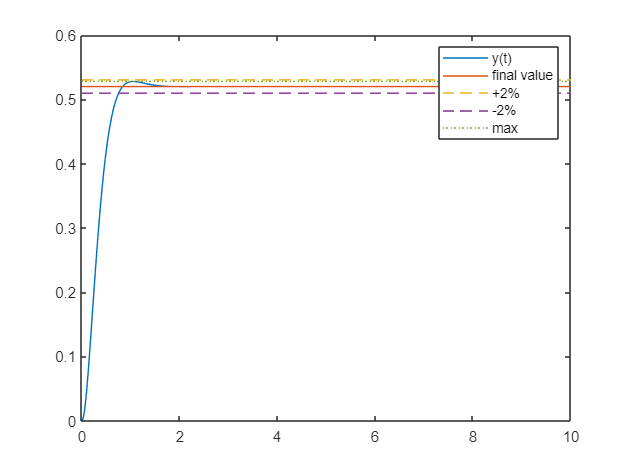

figure
plot(t,y ,t,13/25.*u ,t,13/25.*u.*1.02, '--',t,13/25.*u.*0.98,'--',t,Max.*u,':')
legend("y(t)","final value","+2%","-2%","max")

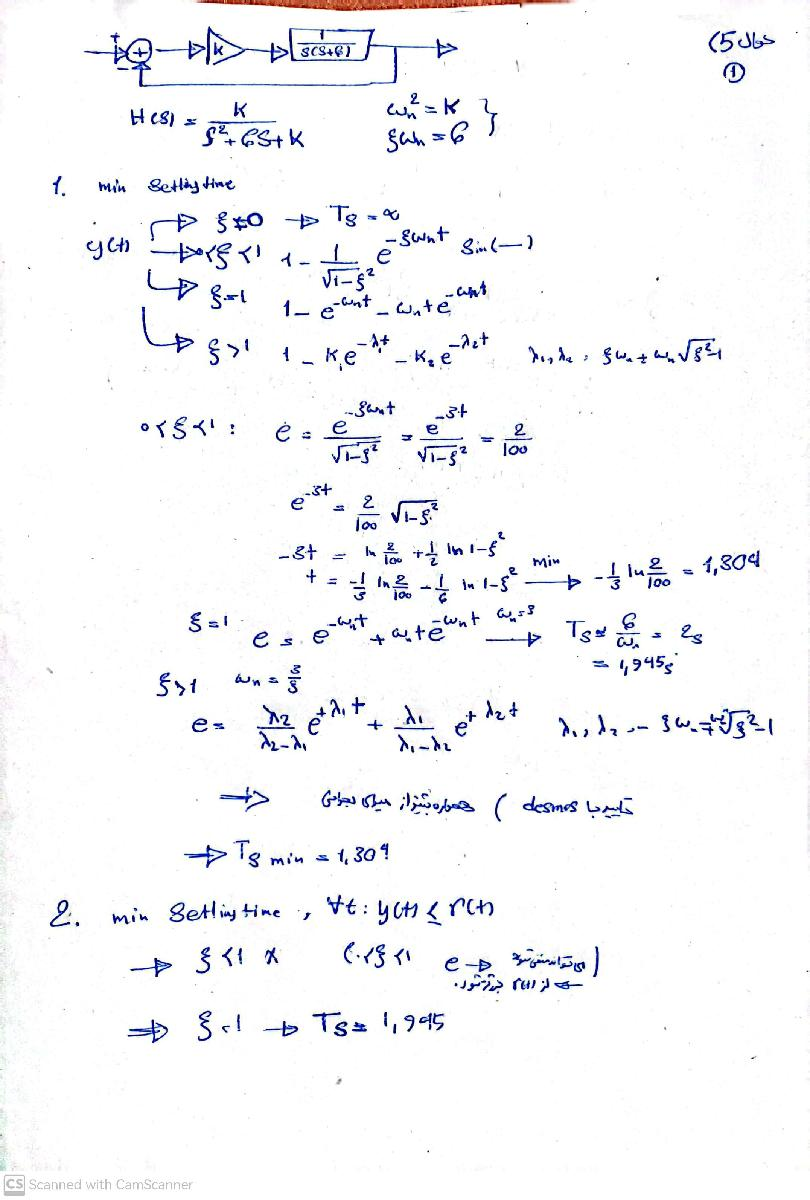

Attached is a video that confirms this.

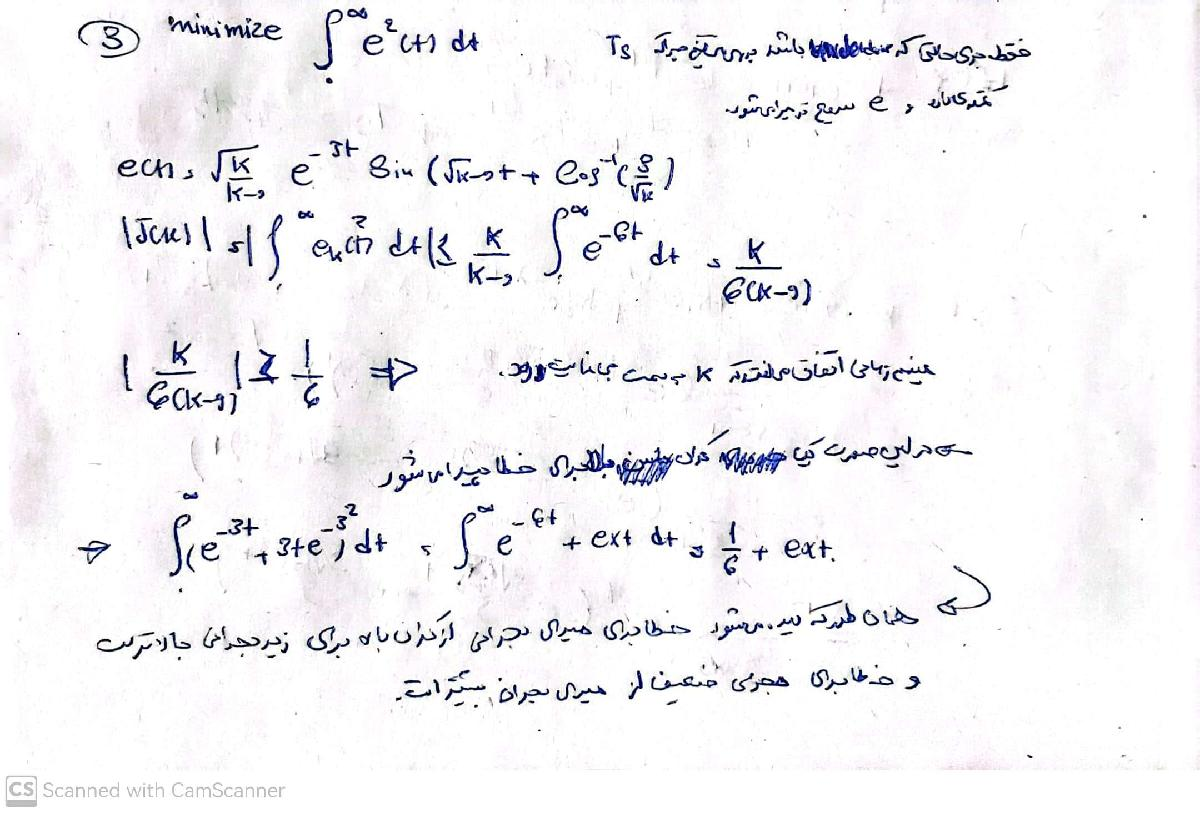

# MATLAB Assignments

clc
close all
clear all

# 6 Symbolic $e^{\mathrm{At}}$

At first, we define an imprecise definition for impulse as a causal signal, then we try to improve the answer with different widths.

1)lsim

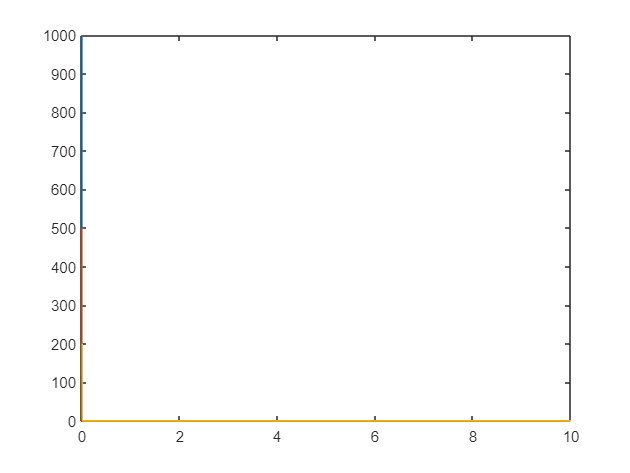

num = [-1 1];
den = [2 3 1];
sys = tf(num, den);

t_1 = 0:0.0001:10;
u  =  impulse_me( 1000 , t_1);
u1 =  impulse_me( 500  , t_1);
u2 =  impulse_me( 200  , t_1);
y_11 = lsim(sys, u, t_1);
y_12 = lsim(sys, u1, t_1);
y_13 = lsim(sys, u2, t_1);

figure
plot(t_1,u,t_1,u1,t_1,u2)
xlim([0 10])

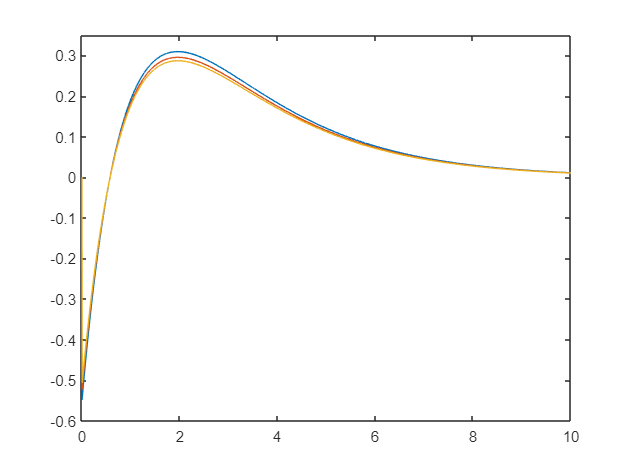

figure
plot(t_1,y_11,t_1,y_12,t_1,y_13)
xlim([0 10])
ylim([-0.6 0.35])

2)ilaplace

We will use the `ilaplace()` function in MATLAB to obtain the inverse Laplace transform of the transfer function, which is equivalent to 

its time-domain impulse response. We will then compare the results to verify their accuracy.

syms s
sys = (1-s)/(2*s^2+3*s+1);

y_2 = ilaplace(sys)

$$y\_2 = \frac{3\,{\mathrm{e}}^{-\frac{t}{2}}}{2}-2\,{\mathrm{e}}^{-t}$$

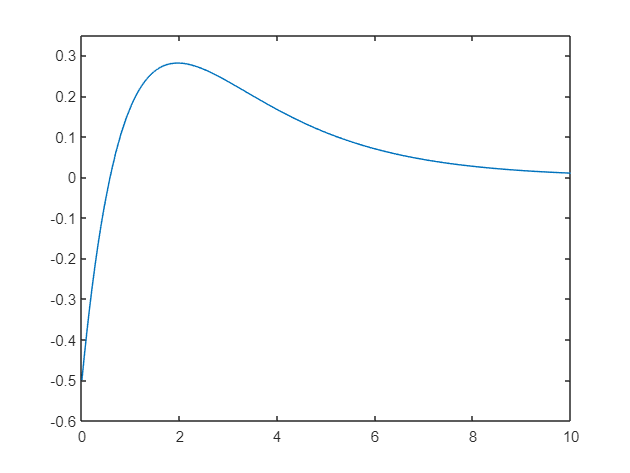


figure
fplot(y_2)
xlim([0 10])
ylim([-0.6 0.35])

3)expm function

We can use the `expm()` function in MATLAB to obtain `eAt`. Then, we can use  equation $y={\textrm{Ce}}^{\textrm{At}} B$  to calculate 

the impulse response.

num = [-1 1];
den = [2 3 1];
sys = tf(num, den);
sys = ss(sys);

syms t
A = sys.A*t;
eAt = expm(A)

$$eAt = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}}\\ 2\,{\mathrm{e}}^{-\frac{t}{2}}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-\frac{t}{2}}-{\mathrm{e}}^{-t} \end{array}\right)$$

eAt3 = eAt;
B = sys.B;
C = sys.C;
impulse_response = C * eAt * B

$$impulse\_response = \frac{3\,{\mathrm{e}}^{-\frac{t}{2}}}{2}-2\,{\mathrm{e}}^{-t}$$

figure
fplot(impulse_response)
xlim([0 10])
ylim([-0.6 0.35])

4)impulse

This is the result of getting the impulse response with impulse() function.

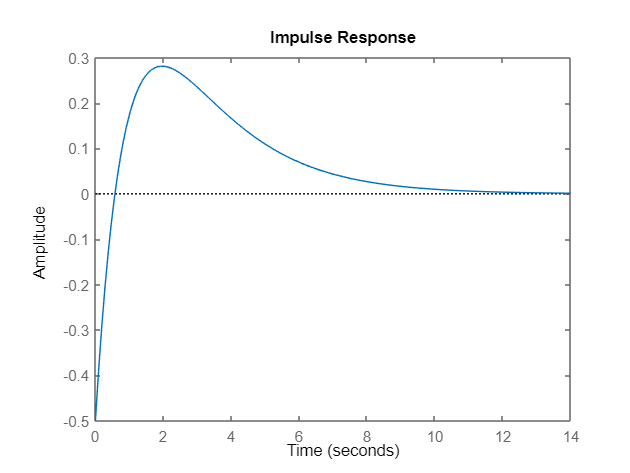

num = [-1 1];
den = [2 3 1];
sys = tf(num, den);

impulse(sys)

5) In this section we compare previews part :

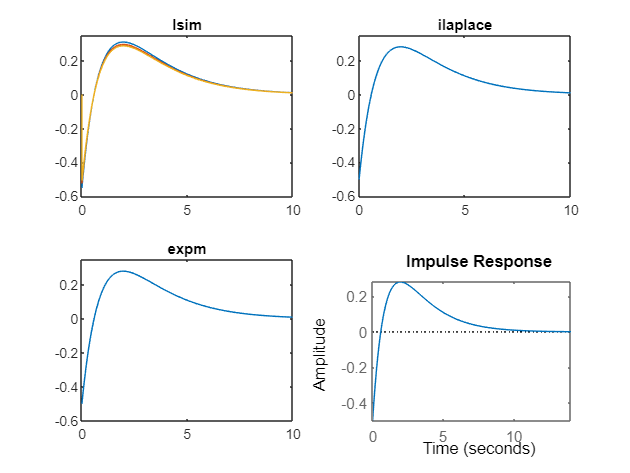

figure %1
subplot(2,2,1)
plot(t_1,y_11,t_1,y_12,t_1,y_13)
title("lsim")
xlim([0 10])
ylim([-0.6 0.35])
subplot(2,2,2) %2
fplot(y_2)
title("ilaplace")
xlim([0 10])
ylim([-0.6 0.35])
subplot(2,2,3) %3
fplot(impulse_response)
title("expm")
xlim([0 10])
ylim([-0.6 0.35])
subplot(2,2,4)
impulse(sys) %4

It's crystal clear that all these plots are showing the impulse response of G(S)

6) As expected $e^{\mathrm{At}}$, matrices calculated from those ways are identical!

num = [-1 1];
den = [2 3 1];
sys = tf(num, den); 
sys = ss(sys);
A = sys.A

A =    -1.5000   -0.5000
    1.0000         0


eAt = ilaplace((s*eye(size(A,1)) - A )^-1)

$$eAt = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}}\\ 2\,{\mathrm{e}}^{-\frac{t}{2}}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-\frac{t}{2}}-{\mathrm{e}}^{-t} \end{array}\right)$$

eAt3

$$eAt3 = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}}\\ 2\,{\mathrm{e}}^{-\frac{t}{2}}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-\frac{t}{2}}-{\mathrm{e}}^{-t} \end{array}\right)$$

as we see ,they are equal

# 7 System 1

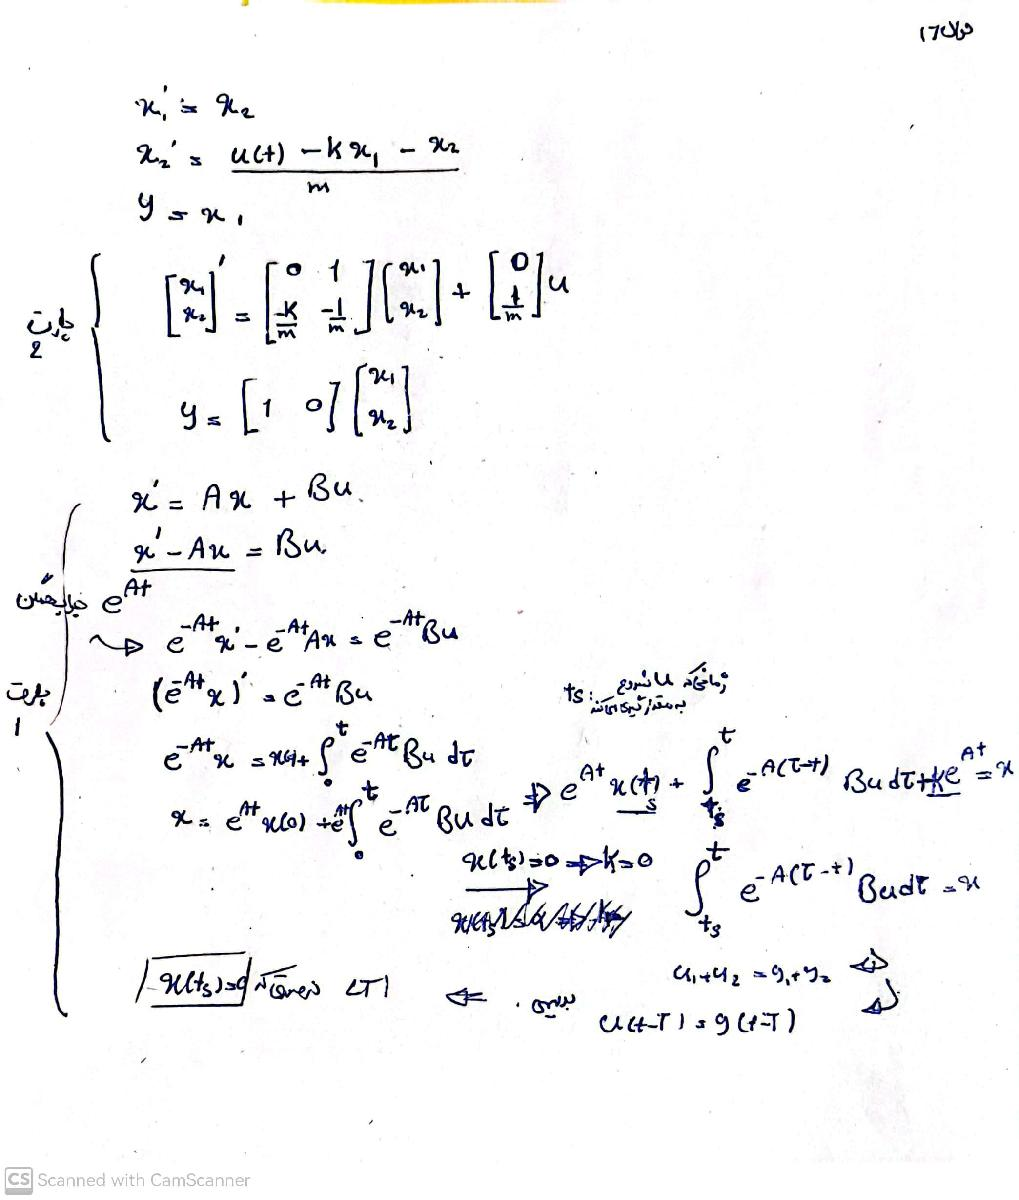

3) finding G(s)

syms k m
A = [0 1;-k/m -1/m];
B = [0 ;1/m];
C = [1 0];
D = 0;

syms s
G = C*(s*eye(size(A))-A)^(-1)*B

$$G = \frac{1}{m\,s^{2}+s+k}$$

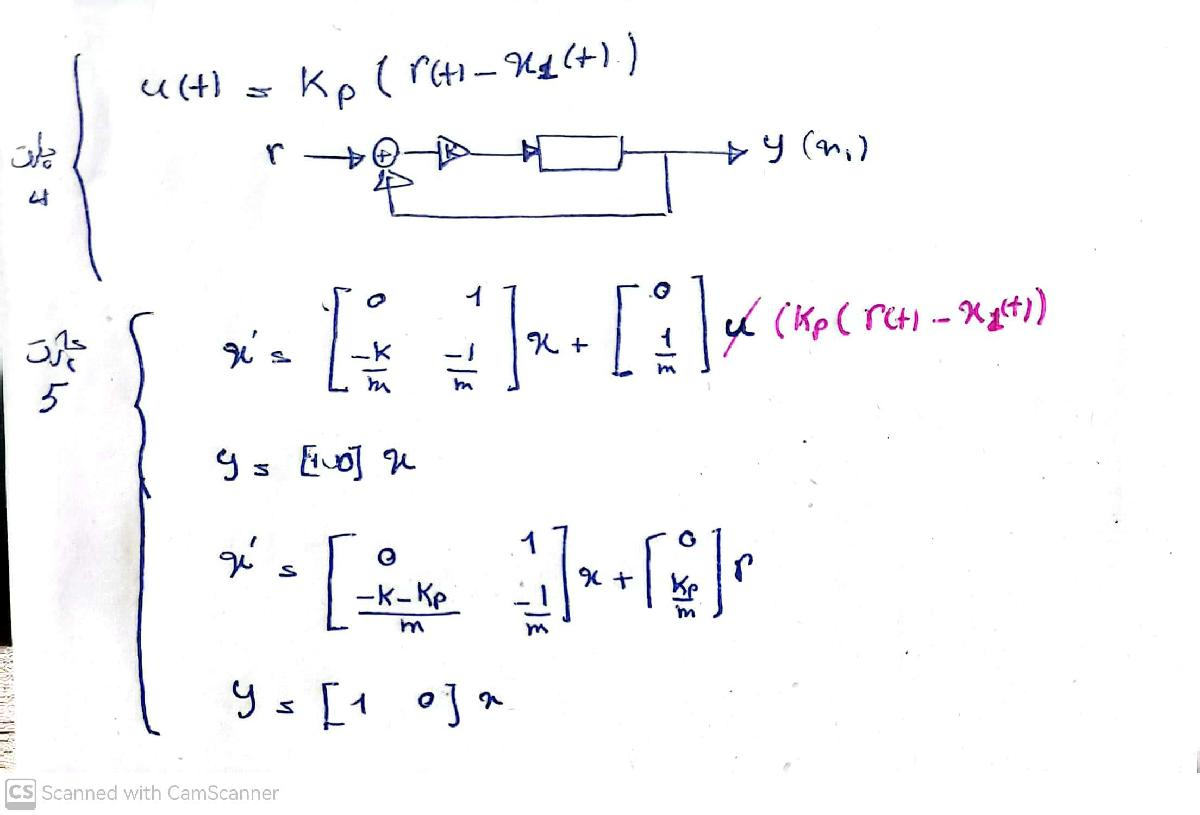

6) finding T(s)

syms k m K
A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;

syms s
T = C*(s*eye(size(A))-A)^(-1)*B

$$T = \frac{K}{m\,s^{2}+s+K+k}$$

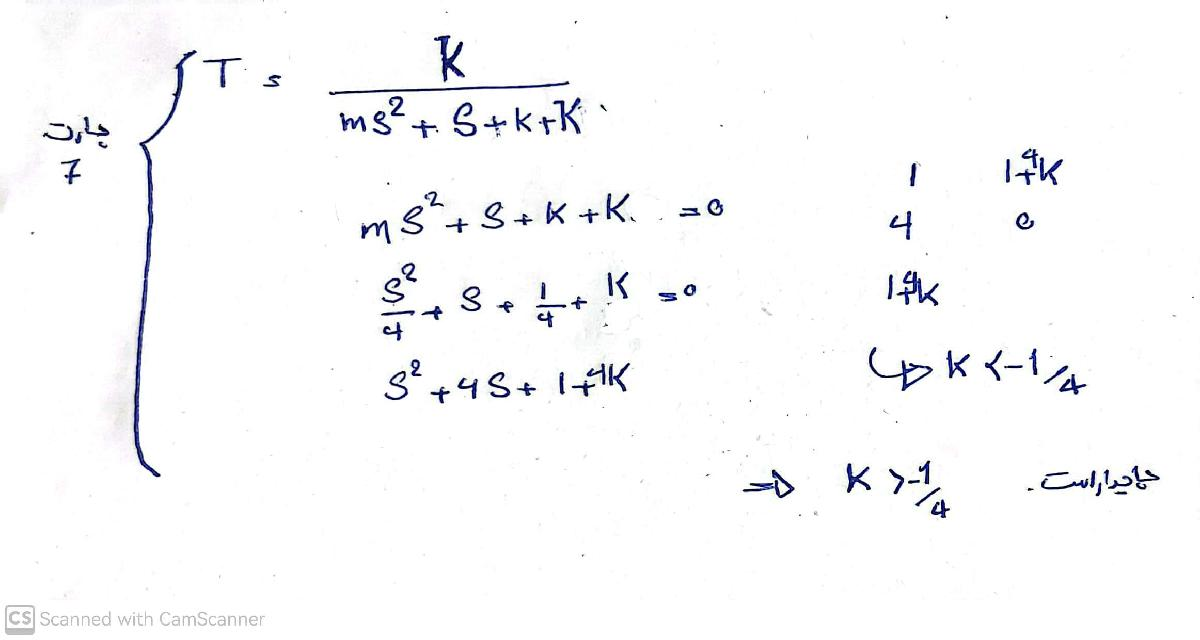

8)

k = 0.25;
m = 0.25;
K = 200;

A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;

syms s
T = C*(s*eye(size(A))-A)^(-1)*B

$$T = \frac{800}{s^{2}+4\,s+801}$$

poles(T,s)

$$ans = \left(\begin{array}{c} -2+\sqrt{797}\,\mathrm{i}\\ -2-\sqrt{797}\,\mathrm{i} \end{array}\right)$$

Considering that the poles and zeros are on the left side of the imaginary axis, then the system is stable

9 )The system per se is unstable as we can see in the figure the output starts to rise monotonically. But using the feedback

 in next part we will stabilize the system.

ode1 Ts=0.01

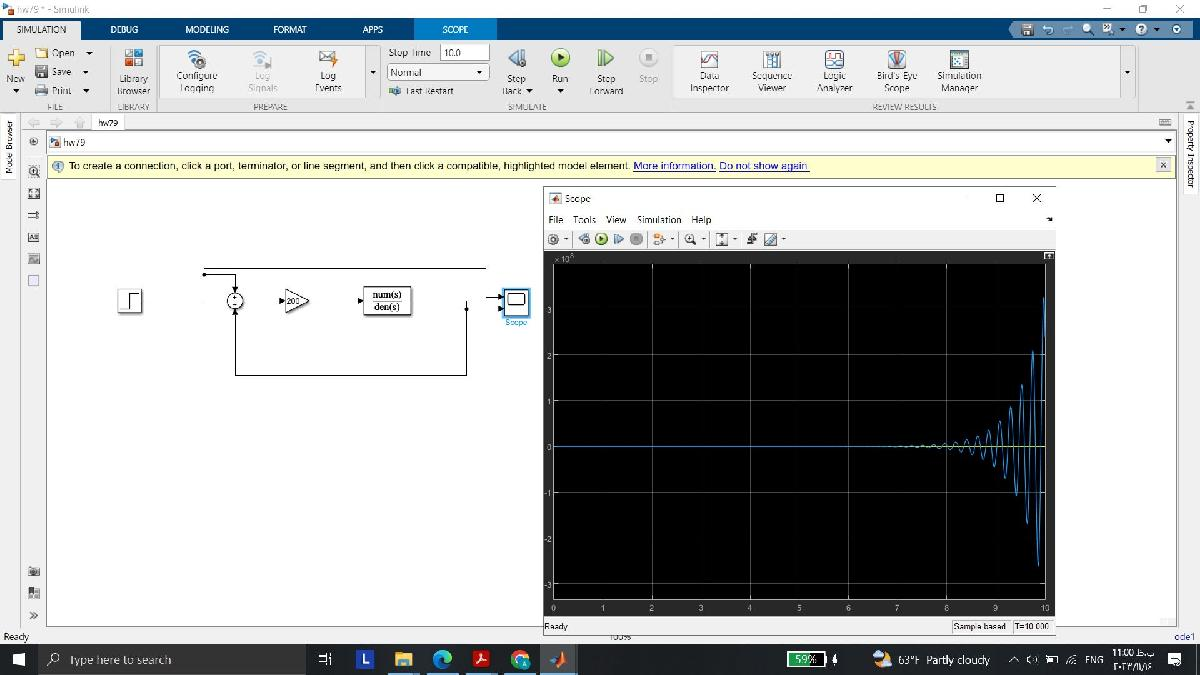

10)

ode1 Ts=0.001

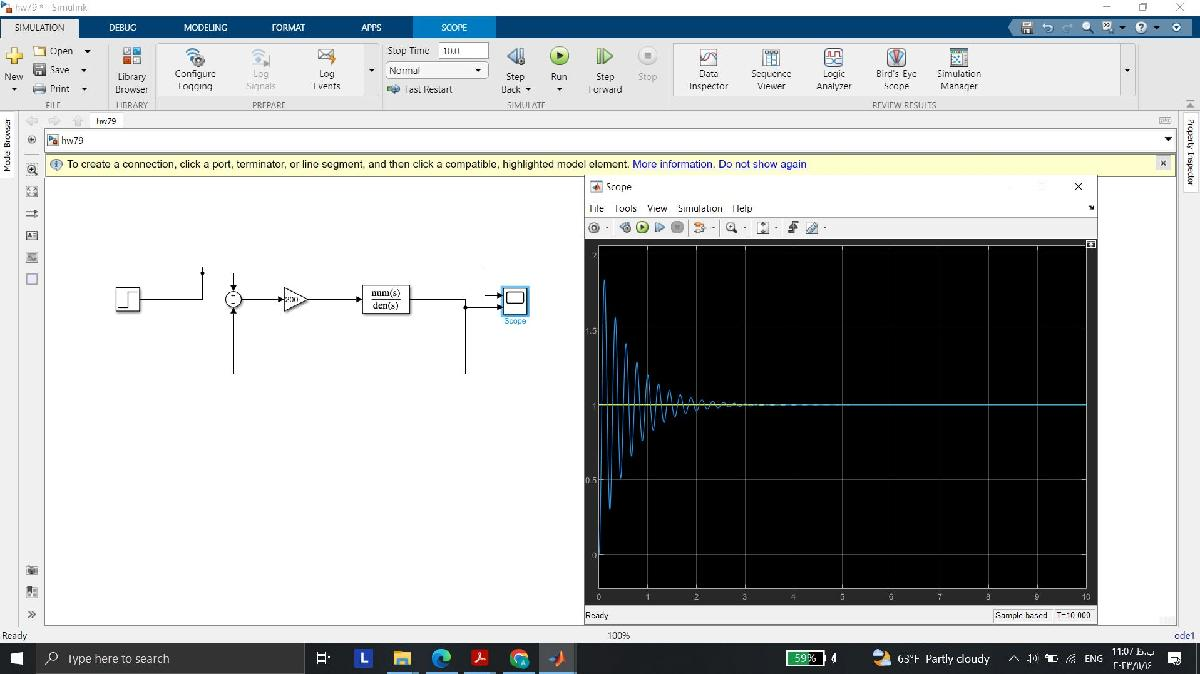

Using the given time step and the solver in the instruction and the results, we can deduce that the system is stable, since by getting bounded 

input we got bunded output and furthermore the output converges to zero as time passes. The feedback indeed stabilized the system!

11)First, we find the permanent error theoretically, then we confirm it by placing a large time in the response equation.

 steady state error:


$$K_p =\lim_{s\longrightarrow 0} \;\frac{K}{{\mathrm{ms}}^2 +s+k}=\;\frac{K}{k}$$



$$e=\frac{A}{1+K_p }=\frac{\mathrm{Ak}}{k+K}$$


k = 0.25;
m = 0.25;
K = 200;

A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;

syms s t
T =  C*(s*eye(size(A))-A)^(-1)*B; 
T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
y_1 = ilaplace(T1);
e_T1=k/(k+K);

k = 5;
m = 0.125;
K = 100;

A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;
e_T2=k/(k+K);
syms s
T =  C*(s*eye(size(A))-A)^(-1)*B; 
T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
y_2 = ilaplace(T1);


k = 10;
m = 3;
K = 50;

A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;
e_T3=k/(k+K);
syms s
T =  C*(s*eye(size(A))-A)^(-1)*B; 
T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
y_3 = ilaplace(T1);

eR1=1-eval(subs(y_1, t, 1000))

eR1 = 0.0012

e_T1

e_T1 = 0.0012

eR2=1-eval(subs(y_2, t, 1000))

eR2 = 0.0476

e_T2

e_T2 = 0.0476

eR3=1-eval(subs(y_3, t, 1000))

eR3 = 0.1667

e_T3

e_T3 = 0.1667

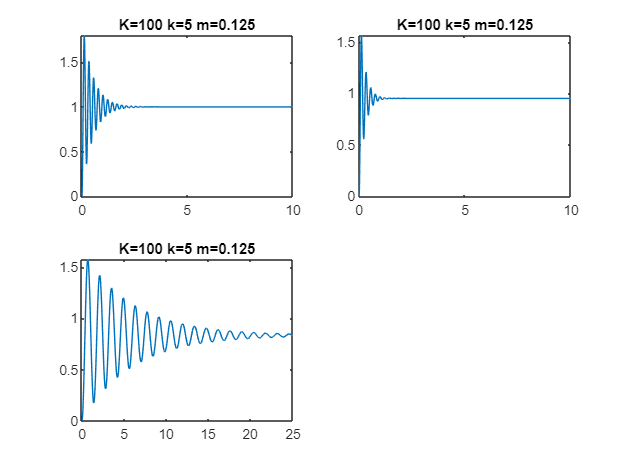

figure
subplot(2,2,1)
fplot(y_1)
title("K=100 k=5 m=0.125")
xlim([0 10])
subplot(2,2,2)
fplot(y_2)
title("K=100 k=5 m=0.125")
xlim([0 10])
subplot(2,2,3)
fplot(y_3)
title("K=100 k=5 m=0.125")
xlim([0 25])

12)We know that $H\left(s\right)=\frac{4k_p }{s^2 +4s+\left(1+4k_p \right)}=\frac{4k_p }{s^2 +2\zeta \omega s+\omega^2 }$. If we want the system to show critically damped behavior, 

 then we must have 𝜁=1which results in $\xi =\frac{2}{\sqrt{1+4k_p }}=1\longrightarrow k_p =0\ldotp 75$.

k = 0.25;
m = 0.25;
K = 0.75;

A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;

syms s
T =  C*(s*eye(size(A))-A)^(-1)*B

$$T = \frac{3}{s^{2}+4\,s+4}$$

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
y = ilaplace(T1)

$$y = \frac{3}{4}-\frac{3\,t\,{\mathrm{e}}^{-2\,t}}{2}-\frac{3\,{\mathrm{e}}^{-2\,t}}{4}$$

eR=1-eval(subs(y, t, 1000))

eR = 0.2500

e_T=k/(k+K)

e_T = 0.2500

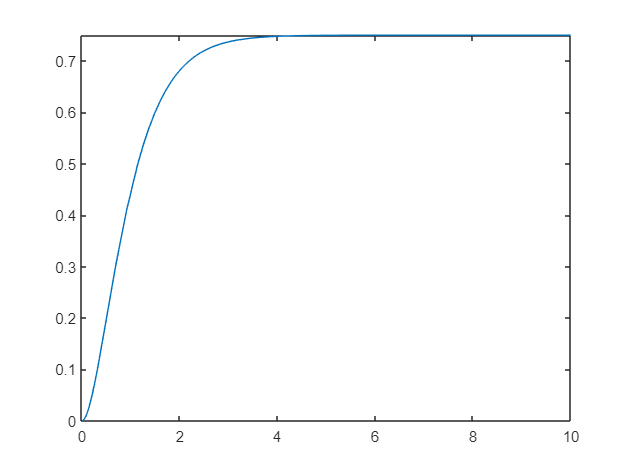

figure
fplot(y)
xlim([0 10])

13)

finding G(s):

clear all

k = 0.25;
m = 0.25;
syms K


A = [0 1;(-(k+K)/m) -1/m];
B = [0 ;K/m];
C = [1 0];
D = 0;

syms s
T =  C*(s*eye(size(A))-A)^(-1)*B

$$T = \frac{4\,K}{s^{2}+4\,s+4\,K+1}$$


$$\begin{array}{l}
\omega_n =\sqrt{4K+1},\zeta \omega_n =2\\
\Rightarrow T_s \;\min :0<\zeta <1\;\Rightarrow K>0\ldotp 75\\
e=\frac{e^{-\xi \omega_n t} }{\sqrt{1-\xi^2 }}=\frac{e^{-2t} }{\sqrt{1-\xi^2 }}<0\ldotp 02\Rightarrow \xi =\varepsilon \Rightarrow T_s \approx 2\\
K=\infty 
\end{array}$$


To prove this, we find settlingtime for different k:

N = 100;
for i=1:N
K = exp(exp(i/20) - 120)
num = [4*K];
dem = [1 4 4*K+1];
sys = tf(num,dem);
settlingTime= stepinfo(sys).SettlingTime
end

K = 2.1939e-52

settlingTime = 14.8789

K = 2.3154e-52

settlingTime = 14.8789

K = 2.4504e-52

settlingTime = 14.8789

K = 2.6008e-52

settlingTime = 14.8789

K = 2.7689e-52

settlingTime = 14.8789

K = 2.9573e-52

settlingTime = 14.8789

K = 3.1692e-52

settlingTime = 14.8789

K = 3.4084e-52

settlingTime = 14.8789

K = 3.6794e-52

settlingTime = 14.8789

K = 3.9874e-52

settlingTime = 14.8789

K = 4.3391e-52

settlingTime = 14.8789

K = 4.7424e-52

settlingTime = 14.8789

K = 5.2068e-52

settlingTime = 14.8789

K = 5.7441e-52

settlingTime = 14.8789

K = 6.3689e-52

settlingTime = 14.8789

K = 7.0991e-52

settlingTime = 14.8789

K = 7.9572e-52

settlingTime = 14.8789

K = 8.9713e-52

settlingTime = 14.8789

K = 1.0177e-51

settlingTime = 14.8789

K = 1.1620e-51

settlingTime = 14.8789

K = 1.3357e-51

settlingTime = 14.8789

K = 1.5465e-51

settlingTime = 14.8789

K = 1.8040e-51

settlingTime = 14.8789

K = 2.1211e-51

settlingTime = 14.8789

K = 2.5148e-51

settlingTime = 14.8789

K = 3.0076e-51

settlingTime = 14.8789

K = 3.6301e-51

settlingTime = 14.8789

K = 4.4240e-51

settlingTime = 14.8789

K = 5.4464e-51

settlingTime = 14.8789

K = 6.7770e-51

settlingTime = 14.8789

K = 8.5276e-51

settlingTime = 14.8789

K = 1.0858e-50

settlingTime = 14.8789

K = 1.3997e-50

settlingTime = 14.8789

K = 1.8280e-50

settlingTime = 14.8789

K = 2.4202e-50

settlingTime = 14.8789

K = 3.2508e-50

settlingTime = 14.8789

K = 4.4330e-50

settlingTime = 14.8789

K = 6.1420e-50

settlingTime = 14.8789

K = 8.6533e-50

settlingTime = 14.8789

K = 1.2408e-49

settlingTime = 14.8789

K = 1.8123e-49

settlingTime = 14.8789

K = 2.6989e-49

settlingTime = 14.8789

K = 4.1022e-49

settlingTime = 14.8789

K = 6.3705e-49

settlingTime = 14.8789

K = 1.0119e-48

settlingTime = 14.8789

K = 1.6459e-48

settlingTime = 14.8789

K = 2.7447e-48

settlingTime = 14.8789

K = 4.6986e-48

settlingTime = 14.8789

K = 8.2683e-48

settlingTime = 14.8789

K = 1.4978e-47

settlingTime = 14.8789

K = 2.7972e-47

settlingTime = 14.8789

K = 5.3937e-47

settlingTime = 14.8789

K = 1.0757e-46

settlingTime = 14.8789

K = 2.2225e-46

settlingTime = 14.8789

K = 4.7662e-46

settlingTime = 14.8789

K = 1.0629e-45

settlingTime = 14.8789

K = 2.4697e-45

settlingTime = 14.8789

K = 5.9923e-45

settlingTime = 14.8789

K = 1.5215e-44

settlingTime = 14.8789

K = 4.0523e-44

settlingTime = 14.8789

K = 1.1349e-43

settlingTime = 14.8789

K = 3.3505e-43

settlingTime = 14.8789

K = 1.0456e-42

settlingTime = 14.8789

K = 3.4594e-42

settlingTime = 14.8789

K = 1.2169e-41

settlingTime = 14.8789

K = 4.5660e-41

settlingTime = 14.8789

K = 1.8333e-40

settlingTime = 14.8789

K = 7.9051e-40

settlingTime = 14.8789

K = 3.6737e-39

settlingTime = 14.8789

K = 1.8472e-38

settlingTime = 14.8789

K = 1.0090e-37

settlingTime = 14.8789

K = 6.0128e-37

settlingTime = 14.8789

K = 3.9264e-36

settlingTime = 14.8789

K = 2.8230e-35

settlingTime = 14.8789

K = 2.2456e-34

settlingTime = 14.8789

K = 1.9867e-33

settlingTime = 14.8789

K = 1.9656e-32

settlingTime = 14.8789

K = 2.1871e-31

settlingTime = 14.8789

K = 2.7536e-30

settlingTime = 14.8789

K = 3.9476e-29

settlingTime = 14.8789

K = 6.4873e-28

settlingTime = 14.8789

K = 1.2306e-26

settlingTime = 14.8789

K = 2.7146e-25

settlingTime = 14.8789

K = 7.0173e-24

settlingTime = 14.8789

K = 2.1432e-22

settlingTime = 14.8789

K = 7.7997e-21

settlingTime = 14.8789

K = 3.4130e-19

settlingTime = 14.8789

K = 1.8127e-17

settlingTime = 14.8789

K = 1.1802e-15

settlingTime = 14.8789

K = 9.5193e-14

settlingTime = 14.8789

K = 9.6160e-12

settlingTime = 14.8789

K = 1.2307e-09

settlingTime = 14.8789

K = 2.0200e-07

settlingTime = 14.8789

K = 4.3064e-05

settlingTime = 14.8762

K = 0.0121

settlingTime = 14.1549

K = 4.5286

settlingTime = 1.9036

K = 2.2994e+03

settlingTime = 1.9361

K = 1.6068e+06

settlingTime = 1.9554

K = 1.5710e+09

settlingTime = 1.9559

K = 2.1861e+12

settlingTime = 1.9549

14

Since $H\left(s\right)=\frac{G\left(s\right)}{G\left(s\right)+1}=\frac{1}{{\textrm{ms}}^2 +s+\left(k+1\right)}$,in order to achive a pure oscillation, we should have $H\left(s\right)=\frac{f_v \omega_0^2 }{s^2 +\omega_0^2 }$

which clearly cnnnot happan!

# 8 System 2

Here are the state-space representation of the open-loop system:


$$\begin{array}{l}
x^{\prime } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{2k}{m} & -\frac{1}{m} & \frac{2k}{m} & 0\\
0 & 0 & 0 & 1\\
\frac{2k}{M} & 0 & -\frac{2k}{M} & -\frac{1}{M}
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\frac{1}{M}
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{cccc}
1\; & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack u
\end{array}$$


2) finding G1 and G2

syms k m M
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; 2*k/M 0 -2*k/M -1/M];
B = [0;0;0;1/M];
C = [1 0 0 0;0 1 0 0];
D = 0;

syms s
G =  C*(s*eye(size(A))-A)^(-1)*B +D

$$G = \left(\begin{array}{c} \frac{2\,k}{4\,k\,s+M\,s^{3}+m\,s^{3}+s^{2}+2\,k\,m\,s^{2}+2\,M\,k\,s^{2}+M\,m\,s^{4}}\\ \frac{2\,k}{4\,k+s+M\,s^{2}+m\,s^{2}+2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^{3}} \end{array}\right)$$

3) replace u(t) with $K_p \left(r\left(t\right)-y\left(t\right)\right)$:


$$\begin{array}{l}
x^{\prime } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{2k}{m} & -\frac{1}{m} & \frac{2k}{m} & 0\\
0 & 0 & 0 & 1\\
\frac{2k-K_p }{M} & 0 & -\frac{2k}{M} & -\frac{1}{M}
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\frac{K_p }{M}
\end{array}\right\rbrack u\\
y_1 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack u
\end{array}$$



$$\begin{array}{l}
x^{\prime } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{2k}{m} & -\frac{1}{m} & \frac{2k}{m} & 0\\
0 & 0 & 0 & 1\\
\frac{2k}{M} & -\frac{K_p }{M} & -\frac{2k}{M} & -\frac{1}{M}
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\frac{K_p }{M}
\end{array}\right\rbrack u\\
y_2 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack u
\end{array}$$



$$T_1 \left(s\right)=\frac{{\textrm{KpG}}_1 \left(s\right)}{1+G_1 \left(s\right)},T_2 \left(s\right)=\frac{{\textrm{KpG}}_2 \left(s\right)}{1+G_2 \left(s\right)}$$


syms k m M Kp
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; (2*k-Kp)/M 0 -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [1 0 0 0];
D = 0;

syms s
T1 =  C*(s*eye(size(A))-A)^(-1)*B +D

$$T1 = \frac{2\,\mathrm{Kp}\,k}{2\,\mathrm{Kp}\,k+4\,k\,s+M\,s^{3}+m\,s^{3}+s^{2}+2\,k\,m\,s^{2}+2\,M\,k\,s^{2}+M\,m\,s^{4}}$$

syms k m M Kp
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; 2*k/M -Kp/M -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [0 1 0 0];
D = 0;

syms s
T2 =  C*(s*eye(size(A))-A)^(-1)*B +D

$$T2 = \frac{2\,\mathrm{Kp}\,k}{4\,k+s+2\,\mathrm{Kp}\,k+M\,s^{2}+m\,s^{2}+2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^{3}}$$

4)


$$\begin{array}{l}
\lim_{s\longrightarrow 0} \left(\begin{array}{c}
\frac{2\,k}{4\,k\,s+M\,s^3 +m\,s^3 +s^2 +2\,k\,m\,s^2 +2\,M\,k\,s^2 +M\,m\,s^4 }\\
\frac{2\,k}{4\,k+s+M\,s^2 +m\,s^2 +2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^3 }
\end{array}\right)=\\
\lim_{s\longrightarrow 0} \left(\begin{array}{c}
\frac{2\,k}{4\,k\,s+M\,s^3 +m\,s^3 +s^2 +2\,k\,m\,s^2 +2\,M\,k\,s^2 +M\,m\,s^4 }\\
\frac{2\,k}{4\,k+s+M\,s^2 +m\,s^2 +2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^3 }
\end{array}\right)=\left\lbrack \begin{array}{c}
\infty \\
0\ldotp 5
\end{array}\right\rbrack =k_p 
\end{array}$$



$$\begin{array}{l}
\lim_{s\longrightarrow 0} \;s\left(\begin{array}{c}
\frac{2\,k}{4\,k\,s+M\,s^3 +m\,s^3 +s^2 +2\,k\,m\,s^2 +2\,M\,k\,s^2 +M\,m\,s^4 }\\
\frac{2\,k}{4\,k+s+M\,s^2 +m\,s^2 +2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^3 }
\end{array}\right)=\\
\lim_{s\longrightarrow 0} \;s\left(\begin{array}{c}
\frac{2\,k}{4\,k\,s+M\,s^3 +m\,s^3 +s^2 +2\,k\,m\,s^2 +2\,M\,k\,s^2 +M\,m\,s^4 }\\
\frac{2\,k}{4\,k+s+M\,s^2 +m\,s^2 +2\,M\,k\,s+2\,k\,m\,s+M\,m\,s^3 }
\end{array}\right)=\left\lbrack \begin{array}{c}
0\ldotp 5\\
0
\end{array}\right\rbrack =k_V 
\end{array}$$


$e_p =\frac{A}{1+K_p }$ ,$e_p =\left\lbrack \begin{array}{c}
0\\
\frac{2}{3}
\end{array}\right\rbrack$

$e_v =\frac{A}{K_v }$ ,$e_v =\left\lbrack \begin{array}{c}
2\\
\infty 
\end{array}\right\rbrack$

k = 10;
m = 1;
M = 1;
Kp = 5;

% case 1
syms s t
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; (2*k-Kp)/M 0 -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [1 0 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
eval(poles(T1))

ans =   -0.5000 + 6.0886i
  -0.5000 - 6.0886i
  -0.5000 + 1.5587i
  -0.5000 - 1.5587i
   0.0000 + 0.0000i


stable 

ys_1 = ilaplace(T1);
T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_1 = ilaplace(T1);

A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; 2*k/M -Kp/M -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [0 1 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
ys_11 = ilaplace(T1);
eval(poles(T1))

ans =    0.5702 + 6.6525i
   0.5702 - 6.6525i
  -3.1403 + 0.0000i
   0.0000 + 0.0000i


unstable

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_11 = ilaplace(T1);
eval(poles(T1))

ans =    0.5702 + 6.6525i
   0.5702 - 6.6525i
  -3.1403 + 0.0000i
   0.0000 + 0.0000i


% case 2
k = 5;
m = 1;
M = 2;
Kp = 1;

syms s t
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; (2*k-Kp)/M 0 -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [1 0 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
ys_2 = ilaplace(T1);
eval(poles(T1))

ans =   -0.3326 - 0.4814i
  -0.3326 + 0.4814i
  -0.4174 + 3.7984i
  -0.4174 - 3.7984i
   0.0000 + 0.0000i


stable

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_2 = ilaplace(T1);
eval(poles(T1))

ans =   -0.3326 - 0.4814i
  -0.3326 + 0.4814i
  -0.4174 + 3.7984i
  -0.4174 - 3.7984i
   0.0000 + 0.0000i


A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; 2*k/M -Kp/M -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [0 1 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
ys_21 = ilaplace(T1);
eval(poles(T1))

ans =   -0.2500 + 3.8649i
  -0.2500 - 3.8649i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i


stable

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_21 = ilaplace(T1);
eval(poles(T1))

ans =   -0.2500 + 3.8649i
  -0.2500 - 3.8649i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i


% case 3
k = 10;
m = 1;
M = 10;
Kp = 100;


syms s t
A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; (2*k-Kp)/M 0 -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [1 0 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
ys_3 = ilaplace(T1);
eval(poles(T1))

ans =    1.0328 + 3.3176i
   1.0328 - 3.3176i
  -1.5828 + 3.7497i
  -1.5828 - 3.7497i
   0.0000 + 0.0000i


unsatble

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_3 = ilaplace(T1);
eval(poles(T1))

ans =    1.0328 + 3.3176i
   1.0328 - 3.3176i
  -1.5828 + 3.7497i
  -1.5828 - 3.7497i
   0.0000 + 0.0000i


A =[0 1 0 0;-2*k/m -1/m 2*k/m 0;
    0 0 0 1; 2*k/M -Kp/M -2*k/M -1/M];
B = [0;0;0;Kp/M];
C = [0 1 0 0];

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s;
ys_31 = ilaplace(T1);
eval(poles(T1))

ans =    1.9266 - 6.1216i
   1.9266 + 6.1216i
  -4.9532 + 0.0000i
   0.0000 + 0.0000i


unsatble

T1 = C*(s*eye(size(A))-A)^(-1)*B * 1/s^2;
yr_31 = ilaplace(T1);
eval(poles(T1))

ans =    1.9266 - 6.1216i
   1.9266 + 6.1216i
  -4.9532 + 0.0000i
   0.0000 + 0.0000i


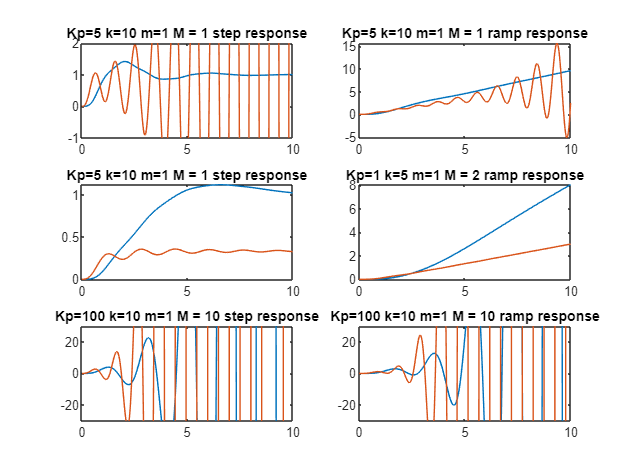

figure
syms t
subplot(3,2,1)
fplot(ys_1)
hold on
fplot(ys_11)
title("Kp=5 k=10 m=1 M = 1 step response")
xlim([0 10])
ylim([-1 2])

subplot(3,2,2)
fplot(yr_1)
hold on
fplot(yr_11)
title("Kp=5 k=10 m=1 M = 1 ramp response")
xlim([0 10])

subplot(3,2,3)
fplot(ys_2)
hold on
fplot(ys_21)
title("Kp=5 k=10 m=1 M = 1 step response")
xlim([0 10])

subplot(3,2,4)
fplot(yr_2)
hold on
fplot(yr_21)
title("Kp=1 k=5 m=1 M = 2 ramp response")
xlim([0 10])

subplot(3,2,5)
fplot(ys_3)
hold on
fplot(ys_31)
title("Kp=100 k=10 m=1 M = 10 step response")
xlim([0 10])
ylim([-30 30])

subplot(3,2,6)
fplot(yr_3)
hold on
fplot(yr_31)
title("Kp=100 k=10 m=1 M = 10 ramp response")
ylim([-30 30])
xlim([0 10])

 2end is stable  ,but 1st and 3th is unstable.

The steady error for the second case is the same as in theory.

In firt case , state 1 is stable but second isn't.

function [u] = impulse_me(e,t)

u = e* (Step01(t) - Step00( t-(1/(e)) ) );
end
function [u] = Step01(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>=0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end
function [u] = Step00(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end